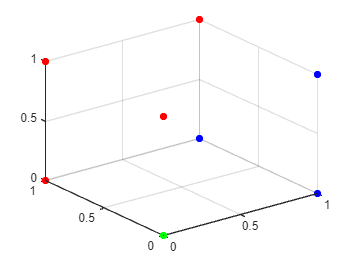

close all
clear all
clc
warning off all

% Mostramos los puntos de la clase 1
PuntosClase1 = [
    0, 0, 0;
    1, 0, 0;
    1, 0, 1;
    1, 1, 0];
PuntosClase2 = [
    0, 0, 1;
    0, 1, 1;
    1, 1, 1;
    0, 1, 0];

figure(1)
scatter3(PuntosClase1(:,1), PuntosClase1(:,2), PuntosClase1(:,3), 'filled', 'b')
hold on
scatter3(PuntosClase2(:,1), PuntosClase2(:,2), PuntosClase2(:,3), 'filled', 'r')
grid on

Individuo = zeros(1, 3);
bandera = 0;

while bandera == 0
    Individuo(1) = input("Ingresa las coordenadas del individuo en x: ");
    Individuo(2) = input("Ingresa las coordenadas del individuo en y: ");
    Individuo(3) = input("Ingresa las coordenadas del individuo en z: ");
    
    if (Individuo(1) >= 0 && Individuo(1) <= 1) && ...
       (Individuo(2) >= 0 && Individuo(2) <= 1) && ...
       (Individuo(3) >= 0 && Individuo(3) <= 1)
        bandera = 1; % Se rompe el bucle
    else
        disp("Error, no se puede clasificar este punto")
    end
end

scatter3(Individuo(1), Individuo(2), Individuo(3), 'filled', 'g');
hold on


% Calcular la media de las clases
MediaClase1 = mean(PuntosClase1);
MediaClase2 = mean(PuntosClase2);

% Matriz de datos centrados
%DatosCentrados1 = PuntosClase1 - MediaClase1;
%DatosCentrados2 = PuntosClase2 - MediaClase2;

% (Individuo - Xcentrado)
XsubtractionY1 = (Individuo - MediaClase1)

XsubtractionY1 =    -0.7500   -0.2500   -0.2500


XsubtractionY2 = (Individuo - MediaClase2)

XsubtractionY2 =    -0.2500   -0.7500   -0.7500



% (Individuo - Xcentrado)'
Transpuesta1 = XsubtractionY1'

Transpuesta1 =    -0.7500
   -0.2500
   -0.2500


Transpuesta2 = XsubtractionY2'

Transpuesta2 =    -0.2500
   -0.7500
   -0.7500



% Matriz de covarianza
Covarianza1 = inv(cov(PuntosClase1))

Covarianza1 =      6    -3    -3
    -3     6     3
    -3     3     6


Covarianza2 = inv(cov(PuntosClase2))

Covarianza2 =      6    -3    -3
    -3     6     3
    -3     3     6



% Distancias de Mahalanobis D^2
DistanciaClase1 = XsubtractionY1 * Covarianza1 * Transpuesta1;
DistanciaClase2 = XsubtractionY2 * Covarianza1 * Transpuesta2;

%Distancia de Mahalanobi D
Dist1 = sqrt(DistanciaClase1);
Dist2 = sqrt(DistanciaClase2);

if Dist1 <= Dist2
    disp('El punto pertenece a la clase 1');
else
    disp('El punto pertenece a la clase 2');
end

El punto pertenece a la clase 1
